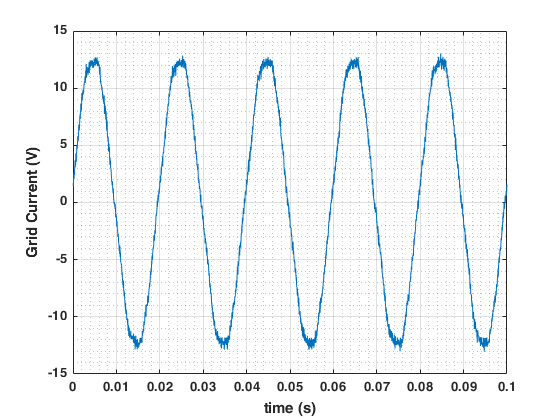

%%% FIRST RUN a.load_data.mlx;

 measurement = meas21;
 grid_current = measurement.V_ch3; %%% corrente no aquecedor

% measurement = meas22;
% grid_current = measurement.V_ch2; %%% corrente na ponte de díodos + motor DC

% measurement = meas23;
% grid_current = measurement.V_ch2;  %%% corrente na ponte de díodos + carga aquecedor

time_vector = measurement.Timestamp;

plot(time_vector, grid_current);
xlabel("time (s)"); ylabel("Grid Current (V)");
grid on; grid minor;

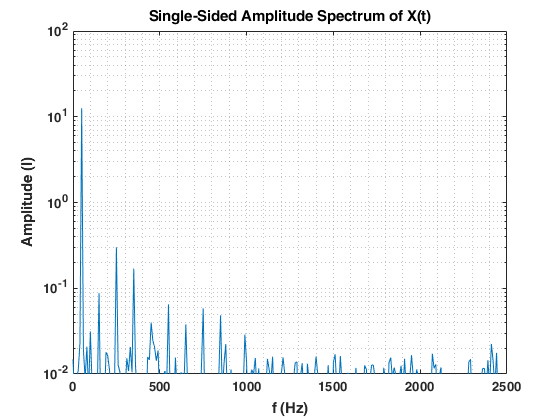

x = grid_current;
Fs = length(grid_current)*10;
L = length(x);
Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
semilogy(f,P1); grid minor;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('Amplitude (I)')
xlim([0 2500]);
ylim([1e-2 1e2]);